# Tutorium 2

Wir betrachten in diesem Tutorium eine Hyper-Kugel $B_n(r)
$ für die gilt


$$r^2 = \sum_{i=1}^{n} x_i^2 \leq 1$$


im Hyperquadranten $[0,1]^n \in \mathbb{R}^n$

## Exakte Lösung

Zunächst haben wir uns die exakte Lösung einer Hyper-Kugel in einer Funktion gespeichert:

$B_n(r) =\frac{\pi^{\frac{n}{2}}}{\gamma \Bigl(\frac{n}{2}+1\Bigr)} \cdot r^n$ mit 


$$\gamma(n + 1) = \int_0^1 t^n e^t \text{d}t$$


#### *Kleine Anmerkung*

Dies muss für **einen** Quadranten entsprechend noch mit $\frac{1}{2^n}$ multipliziert werden. 

*(Man betrachtet nur die positive Intervallhälfte also fallen alle anderen *$2^n -1
$*Kombinationsmöglichkeiten heraus)*

Line = exactSphere(1,1)

Line = 2.0000

Circle = exactSphere(1,2)

Circle = 3.1416

Sphere = exactSphere(1,3)

Sphere = 4.1888

HyperSphere = exactSphere(1,4)

HyperSphere = 4.9348

GoogolSpha = exactSphere(1,100)

GoogolSpha = 2.3682e-40

Bzw. nur für Hauptquadrant:

Line = exactSpherePositiv(1,1)

Line = 1.0000

Circle = exactSpherePositiv(1,2)

Circle = 0.7854

Sphere = exactSpherePositiv(1,3)

Sphere = 0.5236

HyperSphere = exactSpherePositiv(1,4)

HyperSphere = 0.3084

GoogolSpha = exactSpherePositiv(1,100)

GoogolSpha = 1.8682e-70

Das ist ja bemerkenswert, will ich mal kurz plotten:

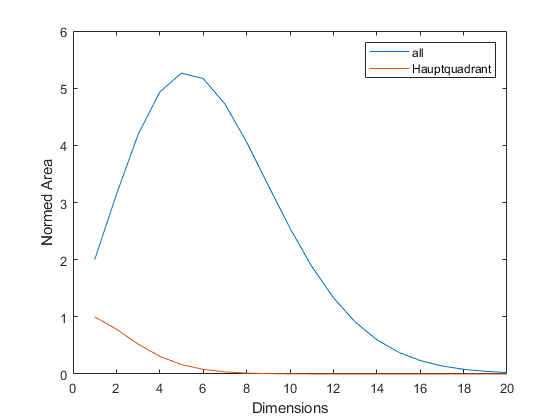

x = 1:20;
hyperSphere = exactSphere(1,x);
plot(x,hyperSphere)
xlabel 'Dimensions'
ylabel 'Normed Area'
hyperSpherePos = exactSpherePositiv(1,x);
hold on
plot(x,hyperSpherePos)
legend('all','Hauptquadrant')
hold off

Wow, das ist nicht intuitiv für mich!

## Numerische Integration:

Nach diesem Kurzen Mind-Fuck, versuchen wir uns jetzt mal an der numerischen Integration dieser Aufgabe:

Im folgenden sollen $m$-Datenpunkte verwendet werden und in der Dimension $n$ Integriert werden

m = 1e6

m = 1000000

n = 2

n = 2

r = 1

r = 1

### Rechtecks-Regel:

Zunächst definieren wir uns ein gleichmäßiges Gitter:

p = round(m^(1/n))

p = 1000

if p < 10
    warning('Few Points for this Dimension')
end

Da wir hier Runden gilt im allgemeinen nicht $m = p^n$ aber es ist die beste Approximation

grid = linspace(0,r,p)

grid =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


for i = 1:n
    grid = grid;
end

Noch besser sind aber in einer Interpreter Sprache die bereits definierten Funktionen hier `ndgrid()`

Ndarrays = cell(1, n); %Das war etwas knifflig, aber so kann ich n-Variablen erzeugen
[Ndarrays{:}] = ndgrid(grid);  %fills all N Nd arrays

Damit bildet sich das Integral über eine einfache Logische Abfrage:

volInt = Ndarrays{1}.^2;
for i = 2:n
    volInt = volInt + Ndarrays{i}.^2;
end

volInt = volInt < 1;
for i = 1:n
    volInt = sum(volInt);
end

%Biene Maya lässt grüßen
%Nun noch die Normierung
unitDimCube = (r/(p-1)).^n

unitDimCube = 1.0020e-06

volInt = unitDimCube .* volInt

volInt = 0.7864

Und damit haben wir unser Ergebnis

### Integration mit Monte Carlo

Dies ist jetzt sehr einfach zu implementieren, wenn wir uns nicht damit beschäftigen, wie der Pseudo-Zufall erzeugt wird.

Zunächst müssen wir zufällige Punkte in $[0,1]^n$ erzeugen

maschinengewehrkugel = 0;
getroffen = 0;
for i = 1:m
    for j = 1:n
       maschinengewehrkugel = maschinengewehrkugel + rand(r).^2;
    end
    if maschinengewehrkugel <= 1
        getroffen = getroffen + 1;
    end
    maschinengewehrkugel = 0;
end
ergebnis = getroffen./m

ergebnis = 0.7849

ergebnis = ergebnis.*(r^n)

ergebnis = 0.7849

#### Approximations Fehler

Nun wollen wir uns den entsprechenden Fehler bei verwendeten Punkten $m$ nochmal genauer anschauen

Dafür schreibe ich die hier durchgearbeite Funktionen in zwei kleine Funktion `NumIntRechteckKugel(r,n,m) `und `MonteCarloSphere(r,n,m)` mit n Nummer der Dimensionen und r als Radius 

Nun berechnen wir diese für verschiedene m in $n = 2$ mit $r = 1$:

start = 5

start = 5

maximum = 20

maximum = 20

exponent = 2

exponent = 2

n = 2

n = 2

r = 1

r = 1

QuadraturRechteck = zeros(1,maximum-start);
QuadraturMonteCarlo = zeros(1,maximum-start);
x = start:maximum

x =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


for i = x
    QuadraturRechteck(i-start+1) = NumIntRechteckKugel(r,n,exponent.^i);
    QuadraturMonteCarlo(i-start+1) = MonteCarloSphere(r,n,exponent.^i);
end

#### Plotten

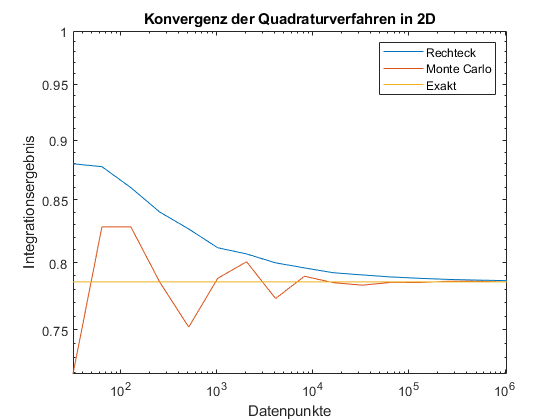

x = exponent.^x;
loglog(x,QuadraturRechteck);
hold on
loglog(x,QuadraturMonteCarlo);
exact = zeros(1,numel(x)) + exactSpherePositiv(r,n);
loglog(x, exact);
title 'Konvergenz der Quadraturverfahren in 2D';
xlabel 'Datenpunkte';
ylabel 'Integrationsergebnis';
axis([0,inf,0,1]);
legend('Rechteck','Monte Carlo','Exakt');
hold off

Der Fehler berechnet sich leicht mit:


$$\Delta =|\tilde{B_n}(r)-B_n(r)|$$


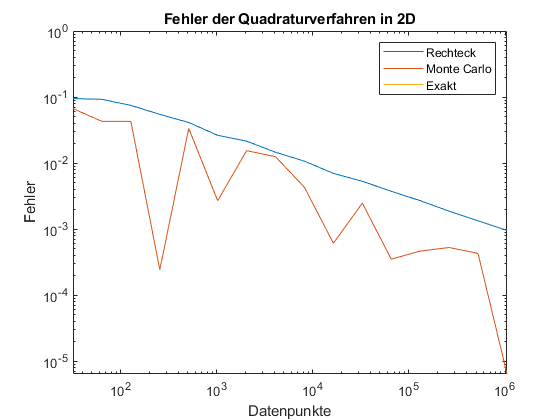

DeltaQRechteck = abs(QuadraturRechteck - exactSpherePositiv(1,2));
DeltaQMonteCarlo = abs(QuadraturMonteCarlo - exactSpherePositiv(1,2));

loglog(x,DeltaQRechteck);
hold on
loglog(x,DeltaQMonteCarlo);
exact = zeros(1,numel(x));
loglog(x, exact);
title 'Fehler der Quadraturverfahren in 2D';
xlabel 'Datenpunkte';
ylabel 'Fehler';
axis([0,inf,0,1]);
legend('Rechteck','Monte Carlo','Exakt');
hold off

### Wir erobern den Raum

Nun können wir einfach das gleiche Konzept für 

n = 3

n = 3

benutzen

%Das ist wirklich der exakt gleiche Code, man muss sich
%hier keine Mühe machen diesen nochmal durchzulesen
QuadraturRechteck = zeros(1,maximum-start);
QuadraturMonteCarlo = zeros(1,maximum-start);
x = start:maximum

x =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


for i = x
    QuadraturRechteck(i-start+1) = NumIntRechteckKugel(r,n,exponent.^i);
    QuadraturMonteCarlo(i-start+1) = MonteCarloSphere(r,n,exponent.^i);
end

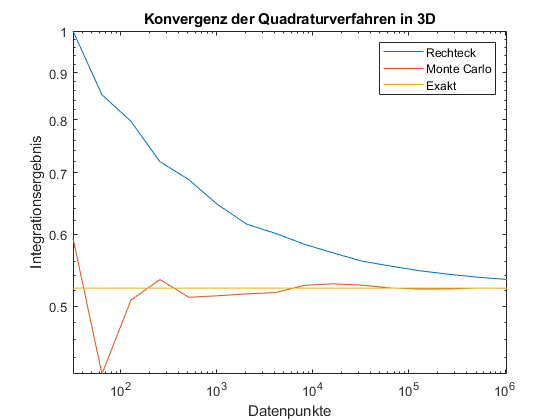


x = exponent.^x;
loglog(x,QuadraturRechteck);
hold on
loglog(x,QuadraturMonteCarlo);
exact = zeros(1,numel(x)) + exactSpherePositiv(r,n);
loglog(x, exact);
title 'Konvergenz der Quadraturverfahren in 3D';
xlabel 'Datenpunkte';
ylabel 'Integrationsergebnis';
axis([0,inf,0,1]);
legend('Rechteck','Monte Carlo','Exakt');
hold off

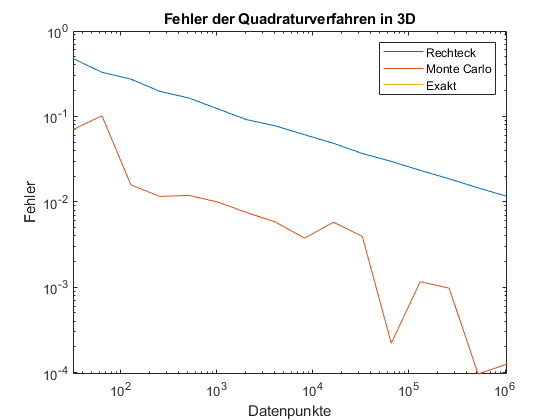


DeltaQRechteck = abs(QuadraturRechteck - exactSpherePositiv(1,n));
DeltaQMonteCarlo = abs(QuadraturMonteCarlo - exactSpherePositiv(1,n));

loglog(x,DeltaQRechteck);
hold on
loglog(x,DeltaQMonteCarlo);
exact = zeros(1,numel(x));
loglog(x, exact);
title 'Fehler der Quadraturverfahren in 3D';
xlabel 'Datenpunkte';
ylabel 'Fehler';
axis([0,inf,0,1]);
legend('Rechteck','Monte Carlo','Exakt');
hold off

### Surface

Das können wir jetzt noch zu einem viel interessanteren Plot kreiren, wenn wir für einen konstanten radius $r = 1$noch zusätzlich die Dimension variieren lassen:

r = 1

r = 1

start = 5

start = 5

maximum = 20

maximum = 20

exponent = 2

exponent = 2


nStart = 1

nStart = 1

nMaximum = 5

nMaximum = 5

siz = [nMaximum-nStart+1 maximum-start+1];
%Initialize variables
surfDataR = zeros(siz);
surfDataMC = zeros(siz);
surfDataE = zeros(siz);
for n = nStart:nMaximum
    %Initialize variables
    QuadraturRechteck = zeros(1,maximum-start);
    QuadraturMonteCarlo = zeros(1,maximum-start);
    
    %Calculate for one fixed n all diffrent methods for m points
    x = start:maximum;
    for i = x
        QuadraturRechteck(i-start+1) = NumIntRechteckKugel(r,n,exponent.^i);
        QuadraturMonteCarlo(i-start+1) = MonteCarloSphere(r,n,exponent.^i);
    end
    
    %Sets the values for the z koordinate
    surfDataR(n-nStart+1,:) = QuadraturRechteck;
    surfDataMC(n-nStart+1,:) = QuadraturMonteCarlo;
    surfDataE(n-nStart+1,:) = surfDataE(n-nStart+1,:) + exactSpherePositiv(r,n);
end

n = 1

n = 2

n = 3

n = 4

n = 5

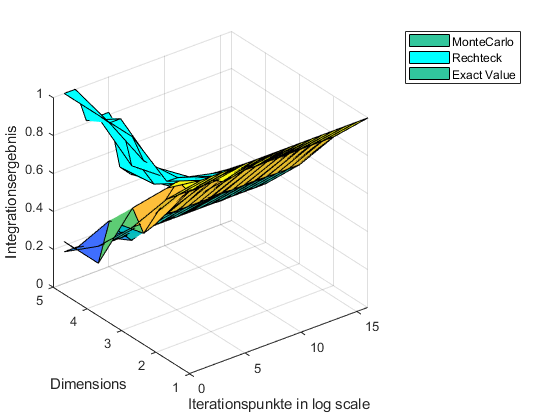

surf(surfDataMC)
hold on
CO(:,:,1) = zeros(siz); % red
CO(:,:,2) = ones(siz); % green
CO(:,:,3) = ones(siz); % blue
surf(surfDataR, CO)
surf(surfDataE)
xlabel('Iterationspunkte in log scale')
ylabel('Dimensions')
zlabel('Integrationsergebnis')
legend('MonteCarlo','Rechteck','Exact Value');
hold off

#### Fehler

Nun noch das gleiche mehrdimensional

DeltaQMonteCarlo = abs(QuadraturMonteCarlo - surfDataE);
DeltaQRechteck = abs(QuadraturRechteck - surfDataE);
surf(DeltaQMonteCarlo);
hold on;
surf(DeltaQRechteck);
xlabel('Iterationspunkte in log scale');
ylabel('Dimensions');
zlabel('Fehler');
legend('MonteCarlo','Rechteck');

*Sorry für meine denglischen Funktionennamen und inkonsistene Sprache*